% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 50;    % number of data points
P_c = linspace(0.1*P_c_ref, 3*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.1*A_t_ref, 10*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.1*A_e_ref, 10*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective_test([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective_test([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective_test([1, 1, A_e(i)/A_e_ref]);
end

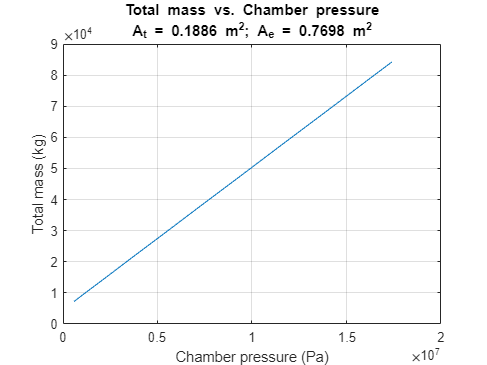

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Total mass (kg)')
title({'Total mass vs. Chamber pressure' 'A_t = 0.1886 m^2; A_e = 0.7698 m^2'})
grid on

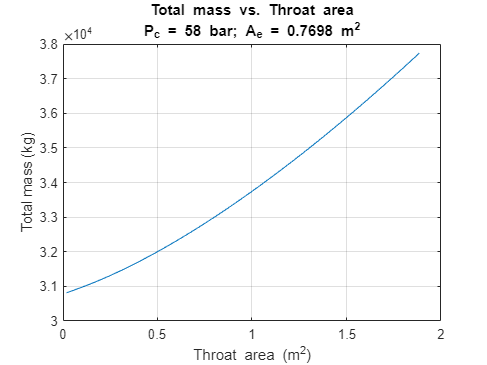


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Total mass (kg)')
title({'Total mass vs. Throat area' 'P_c = 58 bar; A_e = 0.7698 m^2'})
grid on

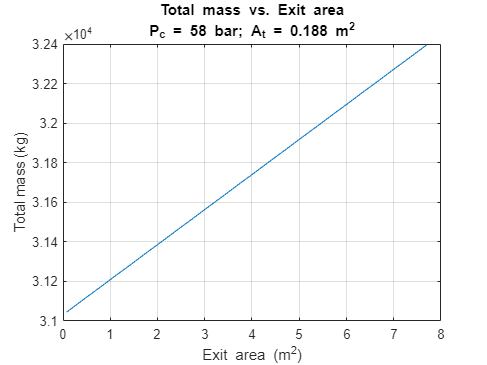


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Total mass (kg)')
title({'Total mass vs. Exit area' 'P_c = 58 bar; A_t = 0.188 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

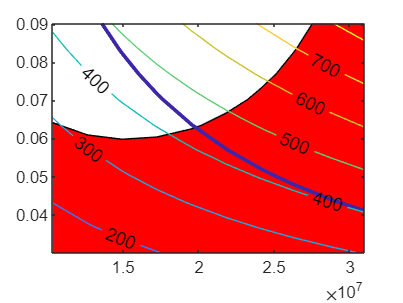

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    2.604219e+04     4.406e-02     1.000e+00     0.000e+00     2.218e+04  
    1           8    6.152156e+03     8.198e-01     1.000e+00     1.547e+00     5.578e+02  
    2          13    8.926728e+03     4.426e-02     7.000e-01     7.362e+00     1.494e+03  
    3          19    9.269363e+03     2.703e-02     4.900e-01     1.729e+00     1.968e+03  
    4          30    9.328998e+03     2.498e-02     8.235e-02     5.133e-01     2.655e+03  
    5          39    9.488268e+03     2.091e-02     1.681e-01     2.482e-01     2.511e+03  
    6          47    9.683684e+03     1.680e-02     2.401e-01     5.059e-01     2.253e+03  
    7          54    9.936820e+03     1.503e-02     3.430e-01     2.940e-01     1.406e+03  
    8          60    1.019950e+04     1.210e-02     4.900e-01     5.028e-01     1.

x =     0.2519    3.8206    7.6273


fval = 1.0554e+04

exitflag = 1

output = struct with fields:
         iterations: 13
          funcCount: 80
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.446500e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.771916e-13, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.7719e-13
           stepsize: 1.1975e-05
       lssteplength: 1
      firstorderopt: 0.0011
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 1.8898e+03
       ineqlin: [0×1 double]
    ineqnonlin: 6.0690e+04
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1460956.104970
Throat area = 0.720574
Exit area = 5.871465
Total Mass = 10554.477501

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
x0 = [0.7, 0.75, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      2784.86       0.4643                                         Infeasible start point
    1      9      2037.84       0.4351          0.5         -615          809   
    2     14       1833.3       0.3869          0.5        -66.3     1.28e+03  Hessian modified  
    3     18      2454.32      0.04263            1          954         51.9   
    4     22      2433.04     0.003425            1        -57.3          111   
    5     32      2429.98       0.0035       0.0156        -46.8         56.9   
    6     37      2419.31     0.004374          0.5        -28.5          103   
    7     41      2418.31     0.002964            1         2.77         2.94   
    8     45      2423.99    2.387e-05            1         94.2         2.37   
    9     49      2424.06    3.992e-07            1         13.9

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 57
       lssteplength: 1
           stepsize: 5.3965e-06
          algorithm: 'active-set'
      firstorderopt: 3.0228e-04
    constrviolation: 3.4539e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.438226e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.453937e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1869326.973832
Throat area = 0.585173
Exit area = 3.203526
Total Mass = 2424.058377

V_UDMH = 78.4286

V_N2O4 = 73.1133

L_UDMH_tank = 5.0736

L_N2O4_tank = 4.5581

t_cyl = 0.0255

t_sph = 0.0127

mass_UDMH_tank = 5.8267e+03

mass_N2O4_tank = 5.2977e+03

chamber_mass = 154.2124

injector_mass = 723.3444

nozzle_divergent_mass = 481.0611

ans = 1.2483e+04

V_UDMH = 16.2008

V_N2O4 = 15.1028

L_UDMH_tank = -1.9876e-05

L_N2O4_tank = -2.2076e-05

t_cyl = 0.0297

t_sph = 0.0149

mass_UDMH_tank = 723.9071

mass_N2O4_tank = 723.9045

ans = 2.4241e+03

calc_objective_test([1, 1, 1])

ans = 2.6042e+04